# **Figure 3: Memory capacity improves with sparse coding and increased population size  **

### Fig B: Generate weight matrix before learning and after learning.

By using theoretical formula of spatial mean and variance we generate the connectivity matrix to show structure for different level of sparseness and network size.

Export figure setup: 7-7

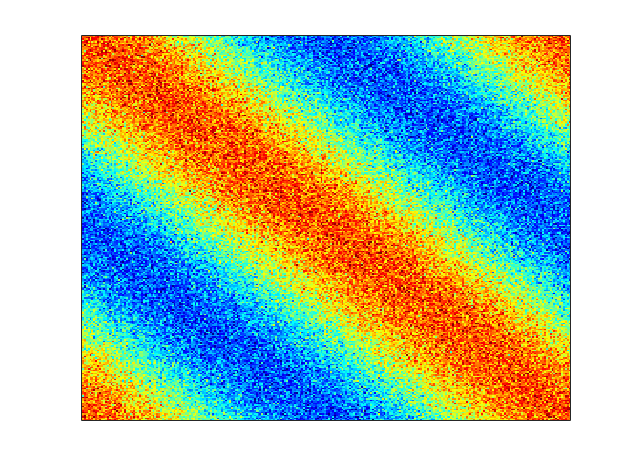

clear; clc;
N = 2^8;  n = 50;  M = 1;  s = 1;  P = 0.3;  D = 0.3;

sy_weight = synthetic_weight(N, P, D, 0, M, s);
imagesc(sy_weight)
colormap(jet(256));
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

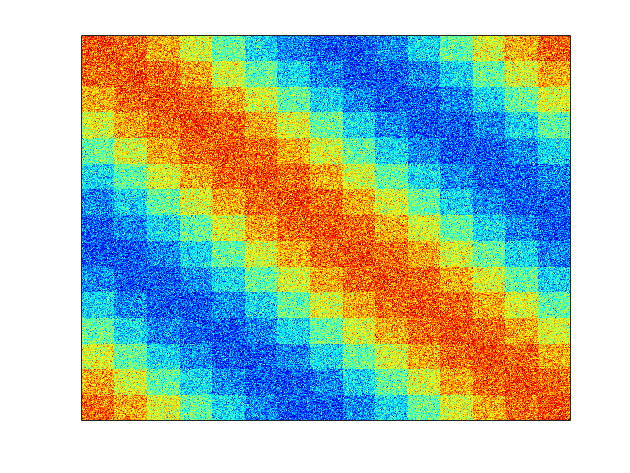


M = 100;
s = 1;
n_ca3_per_track = 15;
sy_weight = synthetic_weight(n_ca3_per_track, P, D, 0, M, s);
imagesc(sy_weight)
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

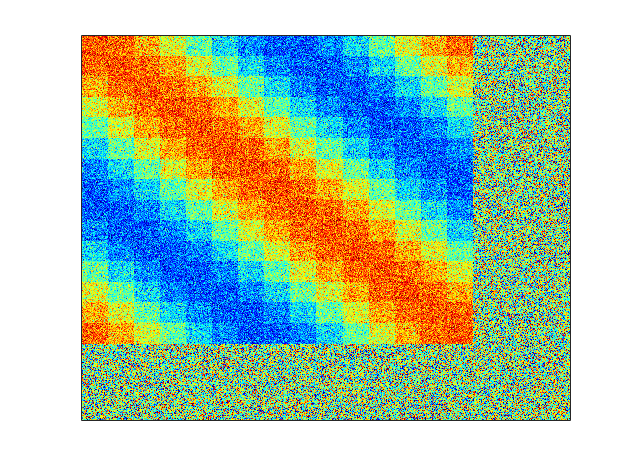


M = 100;
s = 0.8;
sy_weight = synthetic_weight(n_ca3_per_track, P, D, 0, M, s);
imagesc(sy_weight)
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

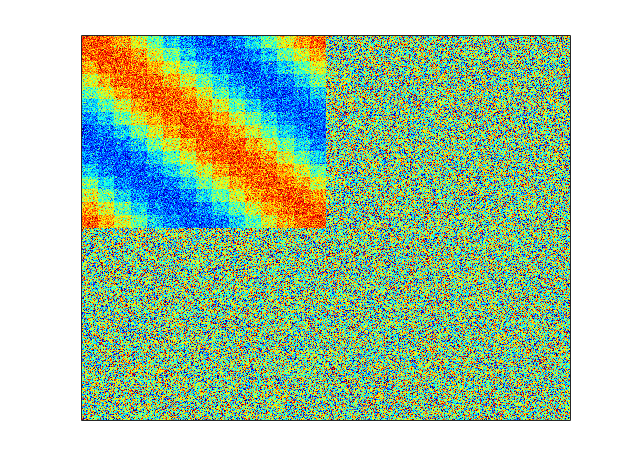



M = 100;
s = 0.5;
sy_weight = synthetic_weight(n_ca3_per_track, P, D, 0, M, s);
imagesc(sy_weight)
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

### Figure C: amplitude and mean variance VS number of past environment $\eta$

Fixing the value of $P=D=0.3$, we run simulation for the recurrent network to obtain weight matrix for different value of $s$ (sparsity) and $M$ (network size). 

Given a value of $s$ and $M$, from the weight matrix at steady state, we compute the amplitude of mean weight as twice of 1st Fourier mode and mean of variance of noise. Later, we compare the simulation results to the theoretical lines.

To present the plot, we run simulation fixing $s$ to 1, and varying $M$ to1, 10, 100. Later, fixing $M = 100$, vary $s = 0.1$ and 0.5. For $s = 1$ is already computed the previous case.

Export figure setup: 4 - 3

inkscape setup: 42.5-31.8750

#### Fix s varying M

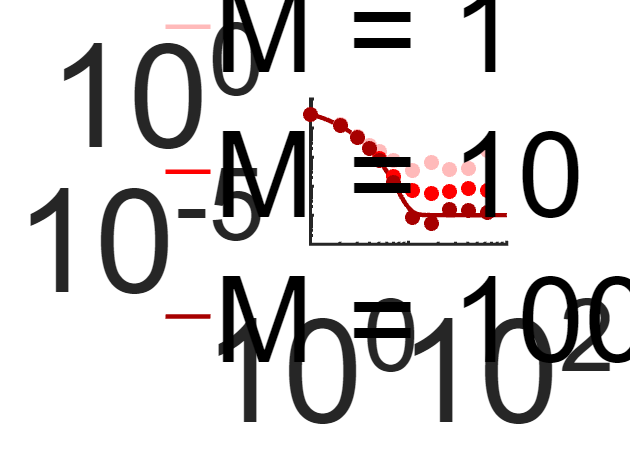

clear; clc;
output_dir = read_output_dir();
load(fullfile(output_dir, "Fig3\mean_var_theo.mat"));
load(fullfile(output_dir, "Fig3\mean_var_s1.mat"));

figure
h = loglog(etas + 1, amplitude_s1 + 0.0001, "-", "LineWidth", 3);
set(h, {'color'}, {[1.0000, 0.7294, 0.7294]; [1, 0, 0]; [0.6549, 0, 0]});
hold on
h2 = loglog(etas_sim + 1, ampl_s1_sim, ".", "MarkerSize", 30);
set(h2, {'color'}, {[1.0000, 0.7294, 0.7294]; [1, 0, 0]; [0.6549, 0, 0]});
qw{1} = plot(nan, "-", "LineWidth", 3, "Color", "[1.0000, 0.7294, 0.7294]");
qw{2} = plot(nan, "-", "LineWidth", 3, "Color", "[1, 0, 0]");
qw{3} = plot(nan, "-", "LineWidth", 3, "Color", "[0.6549, 0, 0]"); % You can add an extra element too
legend([qw{:}], {"M = 1", "M = 10", "M = 100"}, 'location', 'best')
hold off
box off
legend boxoff
ylim([1e-5, 1e0])
yticks([1e-5, 1e-4, 1e-3, 1e-2, 1e-1, 1e0])
yticklabels(["10^{-5}", "", "", "", "", "10^{0}"])
xlim([1e0, 1e2])
xticks([1e0, 1e1, 1e2])
xticklabels(["10^0", "", "10^2"])
fig_config(80)
set(gca, 'LineWidth', 2)

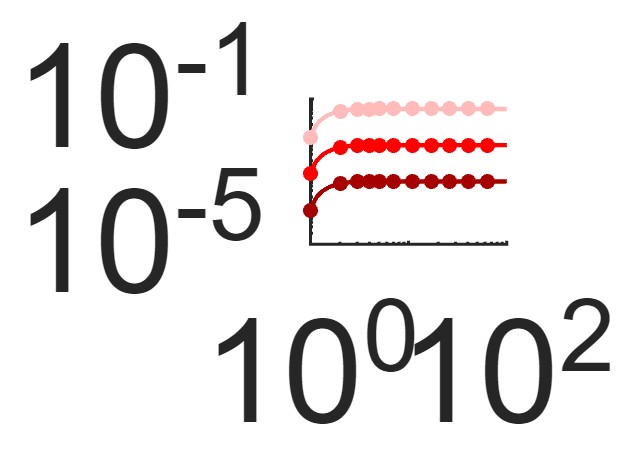


figure
h = loglog(etas + 1, const_var_s1, "-", "LineWidth", 3);
set(h, {'color'}, {[1.0000, 0.7294, 0.7294]; [1, 0, 0]; [0.6549, 0, 0]});
hold on
h2 = loglog(etas_sim + 1, var_s1_sim, ".", "MarkerSize", 30);
set(h2, {'color'}, {[1.0000, 0.7294, 0.7294]; [1, 0, 0]; [0.6549, 0, 0]});
hold off
ylim([1e-5, 1e-1])
yticks([1e-5, 1e-4, 1e-3, 1e-2, 1e-1])
yticklabels(["10^{-5}", "", "", "", "10^{-1}"])
xlim([1e0, 1e2])
xticks([1e0, 1e1, 1e2])
xticklabels(["10^0", "", "10^2"])
box off
fig_config(80)
set(gca, 'LineWidth', 2)

%colorbar

#### Fixing M varying s.

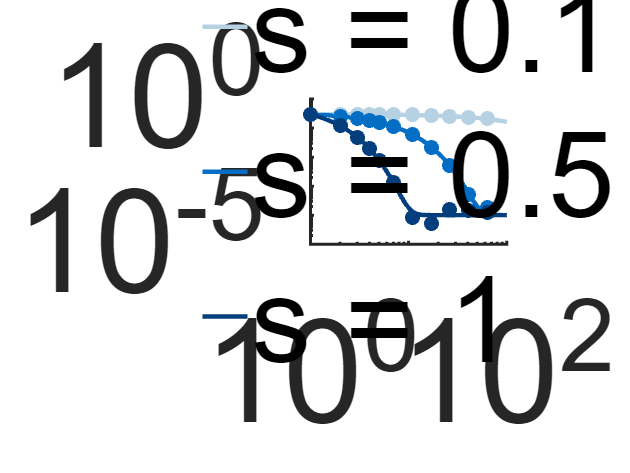

clear; clc;
output_dir = read_output_dir();
load(fullfile(output_dir, "Fig3\mean_var_theo.mat"));
load(fullfile(output_dir, "Fig3\mean_var_M100.mat"));

figure
h = loglog(etas + 1, amplitude_M100 + 0.0001, "-", "LineWidth", 3);
set(h, {'color'}, {[0.7098, 0.8196, 0.8863]; [0.0157, 0.4314, 0.7686]; [0.0157, 0.2431, 0.4902]});
hold on
h2 = loglog(etas_sim + 1, ampl_M100_sim, ".", "MarkerSize", 30);
set(h2, {'color'}, {[0.7098, 0.8196, 0.8863]; [0.0157, 0.4314, 0.7686]; [0.0157, 0.2431, 0.4902]});
qw{1} = plot(nan, "-", "LineWidth", 3, "Color", "[0.7098, 0.8196, 0.8863]");
qw{2} = plot(nan, "-", "LineWidth", 3, "Color", "[0.0157, 0.4314, 0.7686]");
qw{3} = plot(nan, "-", "LineWidth", 3, "Color", "[0.0157, 0.2431, 0.4902]"); % You can add an extra element too
legend([qw{:}], {'s = 0.1','s = 0.5','s = 1'}, 'location', 'best')
hold off
box off
legend boxoff
ylim([1e-5, 1e0])
yticks([1e-5, 1e-4, 1e-3, 1e-2, 1e-1, 1e0])
yticklabels(["10^{-5}", "", "", "", "", "10^{0}"])
xlim([1e0, 1e2])
xticks([1e0, 1e1, 1e2])
xticklabels(["10^0", "", "10^2"])
fig_config(80)
set(gca, 'LineWidth', 2)

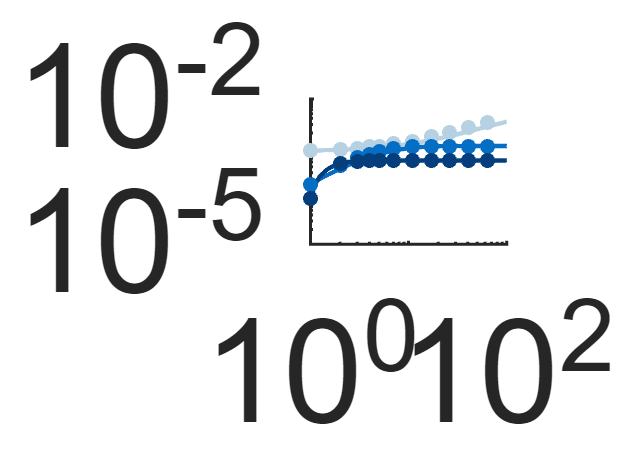


figure
h = loglog(etas + 1, const_var_M100, "-", "LineWidth", 3);
set(h, {'color'}, {[0.7098, 0.8196, 0.8863]; [0.0157, 0.4314, 0.7686]; [0.0157, 0.2431, 0.4902]});
hold on
h2 = loglog(etas_sim + 1, var_M100_sim, ".", "MarkerSize", 30);
set(h2, {'color'}, {[0.7098, 0.8196, 0.8863]; [0.0157, 0.4314, 0.7686]; [0.0157, 0.2431, 0.4902]});
hold off
box off
ylim([1e-5, 1e-2])
yticks([1e-5, 1e-4, 1e-3, 1e-2])
yticklabels(["10^{-5}", "",  "", "10^{-2}"])
xlim([1e0, 1e2])
xticks([1e0, 1e1, 1e2])
xticklabels(["10^0", "", "10^2"])
fig_config(80)
set(gca, 'LineWidth', 2)

### Figure D: Signal-to-noise ratio VS number of past environment $\eta$

Using previous results and theoretical expression, we can compute the SNR (signal-to-noise ratio), the measurement of the quality of memory, to asses the memory capacity fixing a lower bound thereshold.

Export figure setup: 4 - 3

inkscape size: 42.5-31.8750

#### Fixing s = 1

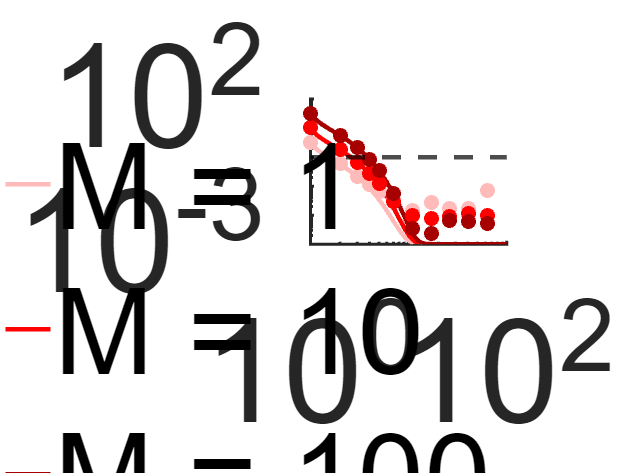

clear; clc;
SNR_f = @(etas, M, s, P) P*(1-2*P*s^2) .^ etas ./ sqrt((P/8/(1-P) - P^2/2*(1-2*P*s^2).^(2*etas))./(s*M));
etas = 0:0.1:100;

% load simulation results
output_dir = read_output_dir();
load(fullfile(output_dir, "Fig3\mean_var_s1.mat"));
SNR_sim_s1 = ampl_s1_sim ./ sqrt(var_s1_sim);

SNR_s1 = [SNR_f(etas, M(3), s, P);SNR_f(etas, M(2), s, P); SNR_f(etas, M(1), s, P)];

figure
h = loglog(etas + 1, SNR_s1+0.001, "-", "LineWidth", 3);
set(h, {'color'}, {[1.0000, 0.7294, 0.7294]; [1, 0, 0]; [0.6549, 0, 0]});
hold on
h2 = loglog(etas_sim + 1, SNR_sim_s1, ".", "MarkerSize", 30);
set(h2, {'color'}, {[1.0000, 0.7294, 0.7294]; [1, 0, 0]; [0.6549, 0, 0]});
yline(1, "--k", "LineWidth", 3)
qw{1} = plot(nan, "-", "LineWidth", 3, "Color", "[1.0000, 0.7294, 0.7294]");
qw{2} = plot(nan, "-", "LineWidth", 3, "Color", "[1, 0, 0]");
qw{3} = plot(nan, "-", "LineWidth", 3, "Color", "[0.6549, 0, 0]"); % You can add an extra element too
legend([qw{:}], {"M = 1", "M = 10", "M = 100"}, 'location', 'northeast')
hold off
legend boxoff
box off
ylim([1e-3, 1e2])
yticks([ 1e-3, 1e-2, 1e-1, 1e0, 1e1, 1e2])
yticklabels(["10^{-3}",  "" "", "", "", "10^{2}"])
xlim([1e0, 1e2])
xticks([1e0, 1e1, 1e2])
xticklabels(["10^0", "", "10^2"])
fig_config(80)
set(gca, 'LineWidth', 2)

####  Fixing the M = 1e2

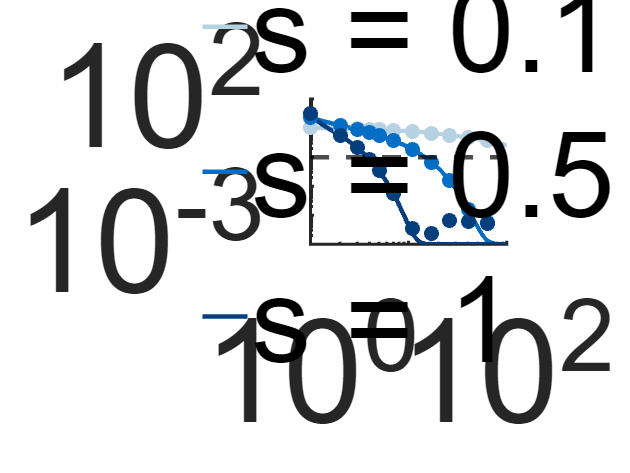

load(fullfile(output_dir, "Fig3\mean_var_M100.mat"));
SNR_sim_M100 = ampl_M100_sim ./ sqrt(var_M100_sim);

s = [s, 1];
SNR_M100 = [SNR_f(etas, M, s(1), P);SNR_f(etas, M, s(2), P); SNR_f(etas, M, s(3), P)];


figure
h = loglog(etas + 1, SNR_M100+0.001, "-", "LineWidth", 3);
set(h, {'color'}, {[0.7098, 0.8196, 0.8863]; [0.0157, 0.4314, 0.7686]; [0.0157, 0.2431, 0.4902]});
yline(1, "--k", "LineWidth", 3)
hold on
h2 = loglog(etas_sim + 1, SNR_sim_M100, ".", "MarkerSize", 30);
set(h2, {'color'}, {[0.7098, 0.8196, 0.8863]; [0.0157, 0.4314, 0.7686]; [0.0157, 0.2431, 0.4902]});
qw{1} = plot(nan, "-", "LineWidth", 3, "Color", "[0.7098, 0.8196, 0.8863]");
qw{2} = plot(nan, "-", "LineWidth", 3, "Color", "[0.0157, 0.4314, 0.7686]");
qw{3} = plot(nan, "-", "LineWidth", 3, "Color", "[0.0157, 0.2431, 0.4902]"); % You can add an extra element too
legend([qw{:}], {'s = 0.1','s = 0.5','s = 1'}, 'location', 'best')
hold off
ylim([1e-3, 1e2])
yticks([ 1e-3, 1e-2, 1e-1, 1e0, 1e1, 1e2])
yticklabels(["10^{-3}",  "" "", "", "", "10^{2}"])
xlim([0, 1e2])
xticks([1e0, 1e1, 1e2])
xticklabels(["10^0", "", "10^2"])
box off
legend boxoff
fig_config(80)
set(gca, 'LineWidth', 2)

####  Memory capacity as function of network size or level of sparsity

The memory capacity is $\eta_{max} = \max_{\eta}{SNR_\eta >= 1}$

clear; clc;
output_dir = read_output_dir();
load(fullfile(output_dir, "Fig3\capacity.mat"));

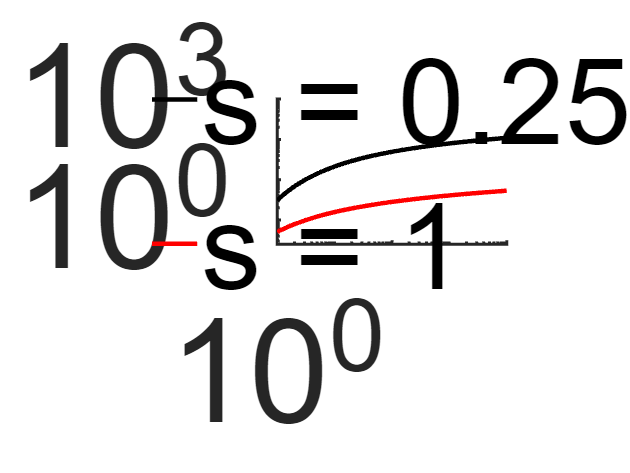


%%%%%%%%%%% x_axis = size of network  %%%%%%%%%%%%%%%%%%
figure
h = loglog(M_1, AsM, "-", "LineWidth", 3);
set(h, {'color'}, {[0, 0, 0]; [1, 0, 0]});
hold on
qw{1} = plot(nan, "-", "LineWidth", 3, "Color", "[0 0 0]");
qw{2} = plot(nan, "-", "LineWidth", 3, "Color", "[1 0 0]");
legend([qw{:}], {'s = 0.25','s = 1'}, 'location', 'best')
hold off
ylim([0.25, 1000])
yticks([1e0, 1e1, 1e2, 1e3])
yticklabels(["10^{0}", "", "", "10^{3}"])
xlim([1e0, 1e4])
box off
legend box off
fig_config(80)
set(gca, 'LineWidth', 2)

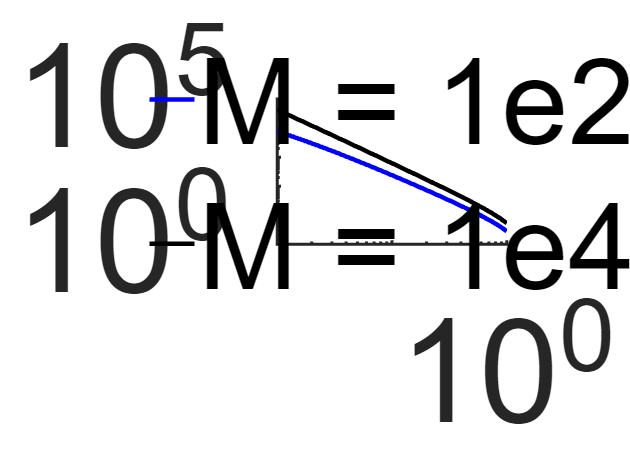


%%%%%%%%%%% x_axis = sparsity  %%%%%%%%%%%%%%%%%%
figure
h = loglog(s_2, AsS, "-", "LineWidth", 3);
set(h, {'color'}, {[0, 0, 1]; [0, 0, 0]});
hold on
qw{1} = plot(nan, "-", "LineWidth", 3, "Color", "[0, 0, 1]");
qw{2} = plot(nan, "-", "LineWidth", 3, "Color", "[0 0 0]");
legend([qw{:}], {'M = 1e2','M = 1e4'}, 'location', 'best')
hold off
ylim([1e0, 1e5])
xlim([1e-2, 1e0])
yticks([1e0, 1e1, 1e2, 1e3, 1e4, 1e5])
yticklabels(["10^{0}", "", "", "", "", "10^{5}"])

box off
legend box off
fig_config(80)
set(gca, 'LineWidth', 2)

## Auxiliar Functions

function amplitude = compute_amplitude(sorted_weight, active_neurons)
    f_fft = fft(sorted_weight, [], 2);
    f_abs = mean(abs(f_fft(:, 2) / active_neurons));
    amplitude = 2 * f_abs;
end 


function Var = compute_variance(sorted_weight, phase)
    phase = unique(phase);
    M = mean(sorted_weight);
    var_sim = var(sorted_weight - M);
    attach_var = var_sim(abs(phase) < 0.3);
    var_sim(abs(phase) < 0.1) = normrnd(mean(attach_var), std(attach_var)/2.5, 1, length(var_sim(abs(phase) < 0.1)));
    Var = mean(var_sim);
end 


function sy_weight = synthetic_weight(n_ca3_per_track, P, D, k, M, Sparsity, w_mean, w_max)
    
    phase_dist = 2 * pi / n_ca3_per_track;              % only a part of net is active during learning
    phase = -pi + phase_dist/2 : phase_dist : pi;       % differnt to the paper, we use -pi to pi 
    phase = phase'; 

    phase = repelem(phase, M * Sparsity);                      % define the phase for multi neurons scenario
    

    if nargin < 8
        w_mean = P/(P+D);
        w_max = 1;
    end

    phase_matrix = squareform(pdist(phase));
    
    % amplitude
    f = @(x, y, k, Sparsity) 2*x*y./(x+y)*(1-Sparsity^2*(x+y)).^k;
    amp = f(P, D, k, Sparsity);

    %M = Multiple_neurons*Sparsity*(P / (P+D) + a_0 * cos(phase'));
    Mean = w_max * (w_mean + amp * cos(phase_matrix'));

    
    [F, F_2, w_m, w_2] = extra_values(P, D, Sparsity);
    
    a_0 = f(P, D, 0, Sparsity);
    A0= P^2 + 2*P*(1-P-D)*w_m+(1-P-D)^2*w_2-w_m^2;
    B0 = 2*(P-D)/(P+D)*(P^2+P*(1-2*P-2*D)*w_m - (P+D)*(1-P-D)*w_2);
    C0 = ((P-D)/(P+D))^2*(P^2-2*P*(P+D)*w_m + (P+D)^2*w_2);
    

    A = A0 * F_2 ^k + w_m^2 * (F_2^k - 1) + ...
        3/2 * P^2 * Sparsity^2 * (1 - F_2^k) / (1 - F_2) + ...
        2*P^2 * Sparsity^4 * (1 - 3/2 * P - 1/2 * D) / (F - F_2) * ( (1-F^k) / (1-F) - (1-F_2^k) / (1-F_2) ) + ...
        2*P * Sparsity^2 * (1 - 3/2 * P - 1/2 * D) * w_m * ( F^k-F_2^k ) / ( F-F_2 );
    B = B0 * F_2^k + 2*a_0 * ( F_2^k - F^(2*k) ) * w_m + ...
        2*a_0 * P * Sparsity^2 * ( (1 - 3/2 * P - 1/2 * D) * (F^k - F_2^k) / (F-F_2) - (F^k - F^(2*k)) /(1-F));
    C = C0*F_2^k +a_0^2*(F_2^k - F^(2*k));
    
    A = A * w_max^2;
    B = B * w_max^2;
    C = C * w_max^2;
    
    %disp(A)
    %disp(A + " " + " " + B + " " + C)
    
    if isnan(A)
        A = 0;
    end
    
    if isnan(B)
        B = 0;
    end
    
    if isnan(C)
        C = 0;
    end
    
    
    V = w_max^2 * (A + B * cos(phase_matrix') + C * (cos(phase_matrix')) .^ 2);
    noise = normrnd(0, sqrt(V));
    
    sy_weight = Mean + noise;
    sy_weight = max(0, min(1, sy_weight));
    [a, b] = size(sy_weight);
    
    mean_value = w_m;
    std_value = sqrt(w_2 - w_m^2);
    
    aux_weight = normrnd(mean_value, std_value, n_ca3_per_track * M, n_ca3_per_track * M );
    aux_weight(1:a, 1:b) = sy_weight;
    
    aux_weight = max(0, min(1, aux_weight));
    
    
    gp = 1:(n_ca3_per_track/Sparsity);
    gp = repelem(gp, M*Sparsity);
    
    %aux_weight = grpstats(aux_weight, gp, {'mean'});
    sy_weight = aux_weight';
end
function [F, F_2, w_m, w_2] = extra_values(P, D, Sparsity)
    F = 1 - Sparsity^2 * (P+D);
    F_2 = 1 + Sparsity^2 * ( 3/2*P^2 + 3/2*D^2 + P*D - 2*P - 2*D );
    w_m = P/(P+D);
    w_2 = (3/2*P^3-1/2*P^2*D-2*P^2)/((P+D)*(3/2*P^2+3/2*D^2+P*D-2*P-2*D));
end



function check_mean_variance(phase, P, D, eta, is_stack, M, s, final_weight, Env_track, N_per_track)
    k = eta;
    [theo_mean, theo_var, phase_theo] = Compute_mean_variance(P, D, k, is_stack, M, s);
    [sort_weight_k, phase_corrected] = Aligment(final_weight, Env_track, k, phase, N_per_track, M, s, is_stack);
    mean_weight = mean(sort_weight_k);
    mean_weight_mod = mean_weight;
    attach_weight = mean_weight(abs(unique(phase_corrected)) < 0.3);
    mean_weight_mod(abs(unique(phase_corrected)) < 0.1) = normrnd(mean(attach_weight), std(attach_weight)/5, ...
        1, length(mean_weight_mod(abs(unique(phase_corrected)) < 0.1)));
    
    
    noise = sort_weight_k - mean_weight;
    var_sim = var(noise);
    figure
    %plot (unique(phase_corrected), sort_weight_k')
    %hold on
    plot(unique(phase_corrected), mean_weight_mod, "k", "LineWidth", 3)
    hold on
    plot(phase_theo, theo_mean, "r", "LineWidth", 2.5)

    hold off
    drawnow
    figure
    plot(phase_corrected, var_sim, "k", "LineWidth", 3)
    hold on
    plot(phase_theo, theo_var, "r", "LineWidth", 3)

    hold off
    drawnow
end